# 1. Visualizing and Understanding Matrix Norms

## (a) 1-norm unit vectors

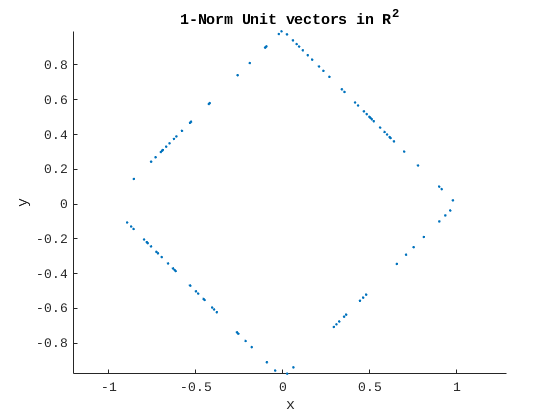

clear
close all

% Declare our paramters
N = 100;
d = 2;

% Generate random vectors
X = randn(N,d);

% Preallocate space for the 1-norm unit vectors
X1 = zeros(N,d);

% Compute 1-norm unit vectors
for i = 1:N
    X1(i,:)  = X(i,:)/norm(X(i,:),1);
end

% Plot unit vecotrs
figure()
scatter(X1(:,1),X1(:,2), '.')
title('1-Norm Unit vectors in R^2')
xlabel('x')
ylabel('y')
axis equal

As expected, 1-norm unit vectors plot out a diamond. The diamond is formed because any 1-norm unit vector satisfies $|x_1| + |x_2| = 1$. This equation has a diamond as a the solution.

## (b) Unit vectors in different norms

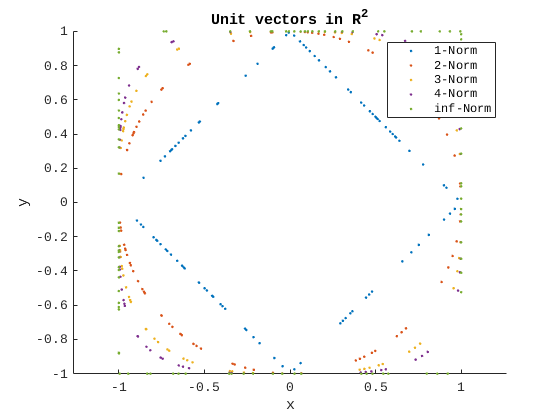

% Preallocate space for the various unit vectors
X2 = zeros(N,d);
X3 = zeros(N,d);
X4 = zeros(N,d);
Xinf = zeros(N,d);

% Compute different unit vectors
for i = 1:N
    X2(i,:)  = X(i,:)/norm(X(i,:),2);
    X3(i,:)  = X(i,:)/norm(X(i,:),3);
    X4(i,:)  = X(i,:)/norm(X(i,:),4);
    Xinf(i,:)  = X(i,:)/norm(X(i,:),Inf);
end

% Plot each unit vector
figure()
scatter(X1(:,1),X1(:,2),'.')
title('Unit vectors in R^2')
xlabel('x')
ylabel('y')
axis equal
hold on
scatter(X2(:,1),X2(:,2),'.')
scatter(X3(:,1),X3(:,2),'.')
scatter(X4(:,1),X4(:,2),'.')
scatter(Xinf(:,1),Xinf(:,2),'.')
legend('1-Norm','2-Norm','3-Norm','4-Norm','inf-Norm')

The 1-norm forms a diamond which is the solution to $|x| + |y| = 1$. The 2-norm produces a circle which satisfies $$x^2+y^2=1$$. As the $n$ increases in the n-norm, the solutions to $|x|^n + |y|^n = 1$ morph into a unit square. Thus the different $n$-norm unit vectors go from a diamond to a circle to a square as $n$ increases.

## (c) A applied to our unit vectors

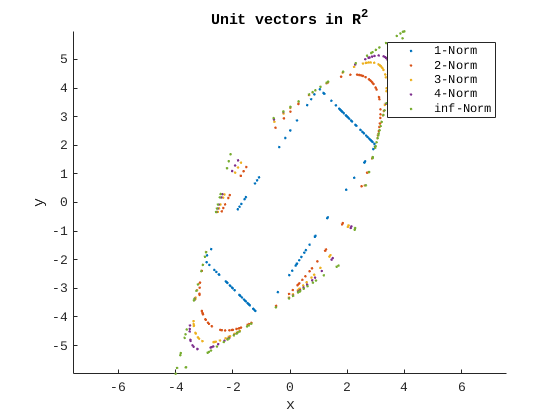

% Define A
A = [1,3;4,2];

% Multiply A by each of our unit vectors
A1 = (A*X1')';
A2 = (A*X2')';
A3 = (A*X3')';
A4 = (A*X4')';
Ainf = (A*Xinf')';

% Plot transformed vectors
figure()
scatter(A1(:,1),A1(:,2),'.')
title('Unit vectors in R^2')
xlabel('x')
ylabel('y')
axis equal
hold on
scatter(A2(:,1),A2(:,2),'.')
scatter(A3(:,1),A3(:,2),'.')
scatter(A4(:,1),A4(:,2),'.')
scatter(Ainf(:,1),Ainf(:,2),'.')
legend('1-Norm','2-Norm','3-Norm','4-Norm','inf-Norm')

As we apply$A$ to each of the unit vectors, the shapes get skewed diaganally. Furthermore, each set of unit vectors are skewed in the same way. The direction and magnitude of the skewing can be understood by looking at the eigenvectors  and eigenvalues of $A$.

## (d) Direct compution of 1-norm and $\infty$-norm of A

% Compute 1-norm of A
A1Norm = max(sum(A,1))

A1Norm =      5


% Compute inf-norm of A
AInfNorm = max(sum(A,2))

AInfNorm =      6


% Compute true 1-norm of A
true1Norm = norm(A,1)

true1Norm =      5


% Compute true inf-norm of A
trueInfNorm = norm(A,Inf)

trueInfNorm =      6


Taking the max row and column sums to compute the 1-norm and inf-norm gives us the correct norms as computed using the built in functions.

## (e) 1-norm and $\infty$-norm approximation

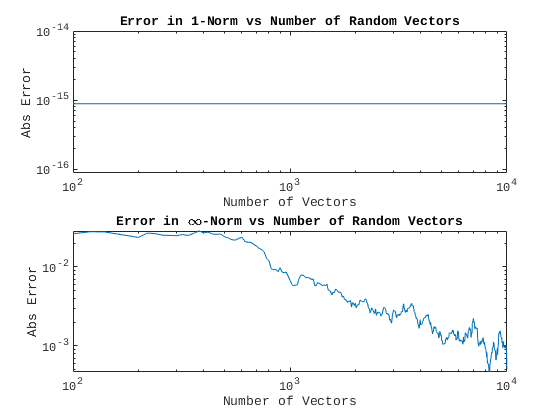

format longE

% Define the different vector amounts to test
N = 100:20:10000;

% Preallocate space for the induced norm errors
errs1 = zeros(length(N),1);
errsInf = zeros(length(N),1);

% Compute induced norm using different numbers of random vectors
for i = 1:length(N)
    % Get random vectors
    X = randn(N(i),d);
    
    % Preallocate space for unit vectors
    X1 = zeros(N(i),d);
    Xinf = zeros(N(i),d);
    
    % Compute unit vectors
    for j = 1:N(i)
        X1(j,:)  = X(j,:)/norm(X(j,:),1);
        Xinf(j,:)  = X(j,:)/norm(X(j,:),Inf);
    end
    
    % Multiply A by the unit vectors
    A1 = (A*X1')';
    Ainf = (A*Xinf')';
    
    % Compute the 1-norm and inf-norm respectively and compute the absolute
    % error of each.
    errs1(i) = abs(max(sum(abs(A1),2)) - true1Norm);
    errsInf(i) = abs(max(max(abs(Ainf))) - trueInfNorm);
end

% Plot the error over various amounts of random vectors
figure()
subplot(2,1,1)
loglog(N,errs1)
title('Error in 1-Norm vs Number of Random Vectors')
xlabel("Number of Vectors")
ylabel("Abs Error")

subplot(2,1,2)
loglog(N,movmean(errsInf,20))
title('Error in \infty-Norm vs Number of Random Vectors')
xlabel("Number of Vectors")
ylabel("Abs Error")

From the plots, we can see that the 1-Norm is accurate for very small sets of vectors. On the other hand, the $\infty$-Norm is not accurate for small sets of vectors. However, the accuracy of computing $\infty$-Norm increases as the number of vectors increases. The $\infty$-Norm is hard to compute using this technique because we need a random unit vector to land on the corner of the unit square. On the other hand, the 1-Norm is easy to compute for this matrix because the induced norm lands on one of the sides of the diamond rather than on the corner. Different matrices would produce different methods.

## (f) 3-norm approximation

% Setup initial conditions
N = 10000;
d = 2;
X = randn(N,d);
A = [1,3;4,2];

% Compute the 3-norm unit vectors
X3 = zeros(N,d);
for i=1:N
    X3(i,:) = X(i,:)/norm(X(i,:),3);
end

% Multiply A by our unit vectors
AX3 = (A*X3')';

% Compute the 3-norm of each multiplied unit vector
Norm_AX3 = zeros(N,1);
for i=1:N
    Norm_AX3(i) = norm(AX3(i,:),3);
end

% Compute the induced 3-norm of A
Norm_3 = max(Norm_AX3)

Norm_3 =      5.222608265156047e+00


Our approximated 3-Norm of A is between the 1-Norm and $\infty$-Norm of A. Furthermore, the 3-Norm is closer to the 1-Norm than the $\infty$-Norm. From these observations, we can conclude that the approximated 3-Norm is reasonable. 

# 2. Matrix Condition Properties

(a) We have $cond(A) = ||A||\;||A^{-1}|| \geq ||A A^{-1}|| = ||I|| = 1$ which implies cond(A) $\geq$1.

(b) We have $cond(I) = ||I||\;||I^{-1}|| = 1\cdot 1 = 1$ which implies cond(I) = 1.

(c) We have $cond(c A) = ||cA||\;||(cA)^{-1}|| = ||cA||\;||\left(\frac{1}{c} A^{-1}\right)|| = c \frac{1}{c} ||A||\;||A^{-1}|| = cond(A)$.

(d) We have $cond(D) = ||D|| ||D^{-1}|| = \max{|d_i|}\cdot \max{\frac{1}{|d_i|}} = \max{|d_i|} \frac{1}{\min{|d_i|}} = \frac{\max{|d_i|}}{\min{|d_i|}}$ which implies $cond(D) = \frac{\max{|d_i|}}{\min{|d_i|}}.$

# 3. Vanderonde Conditioning

## (a) Inital code test

format long

% Compute x and f(x) at 3 equa-spaced points
n = 3;
x = linspace(-1,1,n);
f = x.^2;

% Compute polynomial interpolant coefficients
coeff = my_polyfit(x,f,1)

coeff =      0
     0
     1


Our code is producing the correct coefficients!

## (b) Vandermonde conditioning using the 1-norm:

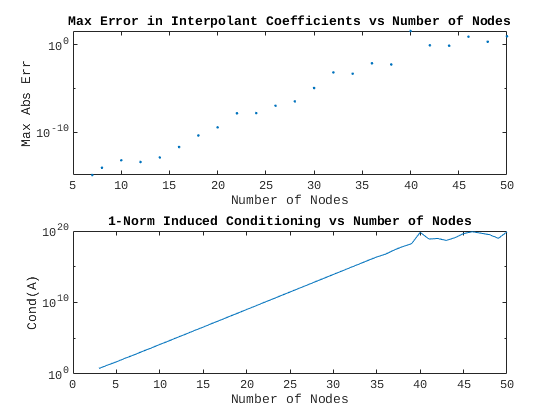

warning('off', 'MATLAB:nearlySingularMatrix')
n = 3:50;

% Preallocate space for the error and conditioning of our interpolant
errs = zeros(length(n),1);
conds = zeros(length(n),1);

% Compute the error and conditioning of our interpolants with different
% amounts of data points
for i = 1:length(n)
    x = linspace(-1,1,n(i));
    f = x.^2;
    
    % Compute coefficients and 1-norm induced condtion number
    [coeff, conds(i)] = my_polyfit(x,f,1);
    
    % Compute the max absolute error of our interpolant coefficients
    coeff(3) = coeff(3) - 1;
    errs(i) = max(abs(coeff));
end

% Plot the error and conditioning of our problem
figure()
subplot(2,1,1)
semilogy(n,errs,'.')
title('Max Error in Interpolant Coefficients vs Number of Nodes')
xlabel('Number of Nodes')
ylabel('Max Abs Err')
subplot(2,1,2)
semilogy(n,conds)
title('1-Norm Induced Conditioning vs Number of Nodes')
xlabel('Number of Nodes')
ylabel('Cond(A)')

From the plots, we can see a direct relation between the condition number and error of our interpolant coefficients. As the 1-norm induced condtion number increases, the max absolute error in the coefficients increase. This relation is exactly what we would expect; the more ill-conditioned the problem, the harder it is to get accurate results.

## (c) Vandermonde conditioning using the 1-norm:

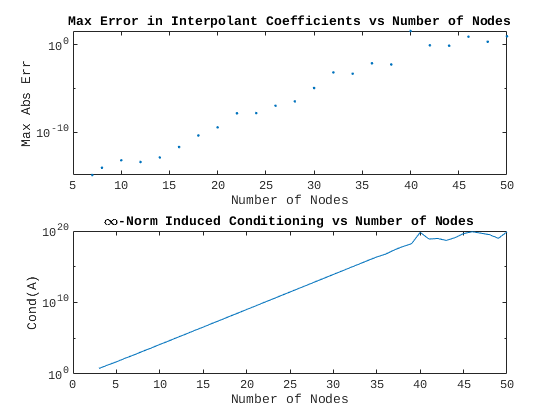

% Compute the error and conditioning of our interpolants with different
% amounts of data points
for i = 1:length(n)
    x = linspace(-1,1,n(i));
    f = x.^2;
    
    % Compute coefficients and inf-norm induced condtion number
    [coeff, conds(i)] = my_polyfit(x,f,1);
    
    % Compute the max absolute error of our interpolant coefficients
    coeff(3) = coeff(3) - 1;
    errs(i) = max(abs(coeff));
end

% Plot the error and conditioning of our problem
figure()
subplot(2,1,1)
semilogy(n,errs,'.')
title('Max Error in Interpolant Coefficients vs Number of Nodes')
xlabel('Number of Nodes')
ylabel('Max Abs Err')
subplot(2,1,2)
semilogy(n,conds)
title('\infty-Norm Induced Conditioning vs Number of Nodes')
xlabel('Number of Nodes')
ylabel('Cond(A)')

Similar to part b, the conditioning and error are directly correlated. Both the max absolute error and the $\infty$-norm induced condition number increase with the number of nodes used. Thus because the plots are so similar, we can conclude that the condition number is almost unaffected by the choice of norm used. Therefore, the condition number is decent proxy for error regardless of the norm used.

# 4. Chebyshev Nodes

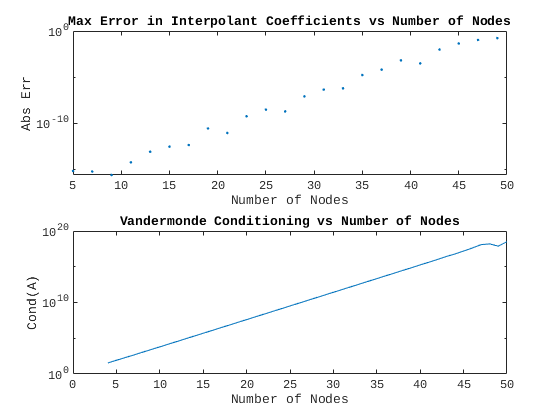

% Number of nodes to use
n = 4:50;

% Preallocate space for the errors and condition numbers
errs = zeros(length(n),1);
conds = zeros(length(n),1);

% Compute error in the coefficients and condition numbers of our problem
for i = 1:length(n)
    x = cos(pi*[0:n(i)] / n(i));
    f = x.^2;
    [coeff, conds(i)] = my_polyfit(x,f,1);
    
    coeff(3) = coeff(3) - 1;
    errs(i) = max(abs(coeff));
end

% Plot the error and conditon numbers
figure()
subplot(2,1,1)
semilogy(n,errs,'.')
title('Max Error in Interpolant Coefficients vs Number of Nodes')
xlabel('Number of Nodes')
ylabel('Abs Err')
subplot(2,1,2)
semilogy(n,conds)
title('Vandermonde Conditioning vs Number of Nodes')
xlabel('Number of Nodes')
ylabel('Cond(A)')

The conditioning of the Vandermonde matrix using Chevyshev nodes appears to be more well conditioned than the equispaced nodes. This is evident from the error plots where the error approaches 1 earlier when using equispaced nodes. Furthermore, the conditioning of the Chebyshev nodes never hits$10^{20}$ while the equispaced nodes do. 

function [coeff, cond_num] = my_polyfit(x,f,p)
    % Compute number of points in x
    n = length(x);
    
    % Preallocate the polynomial matrix
    A = zeros(n);
    
    % Populate the polynomial matrix
    for i = 0:n-1
       A(:,i+1) = x.^i;
    end
    
    % Solve for the coefficients
    coeff = A\(f');
    
    % Compute condition number
    cond_num = cond(A,p);
end